clear;clc;close all

%% 初始参数
p = parameters();

%% 初始条件
initial_state = zeros(10,1);
initial_state(1) = 0.5;%初始状态向量x位置
initial_state(3) = 0.5;
initial_state(5) = p.l0; % 设置初始绳长

%% 仿真参数
t_start = 0;%仿真开始时间
t_end = 15;%仿真结束时间
tspan = [t_start t_end];

%% 由于电机输入
%desired_acceleration_profile = @(t) design_acceleration_profile(t);
control_input_profile = @(t) design_velocity_profile(t);%定义以时间t为自变量的函数

%% 使用ode45求解器进行仿真
tic;%启动计时器

% 设置ode45选项，包括事件检测
options = odeset('Events', @(t,y) limitEvents(t,y,p), 'RelTol', 1e-6, 'AbsTol', 1e-8);%事件检测机制

% 初始化仿真状态
current_time = t_start;%当前仿真事件
current_state = initial_state;%当前系统状态
all_time = [];%用于存储所有事件点
all_states = [];%用于储存所有状态

while current_time < t_end
    % 计算剩余仿真时间
    remaining_time = t_end - current_time;
    current_tspan = [current_time, current_time + remaining_time];%当前仿真事件区间
    
    % 运行ode45直到下一个事件或仿真结束
    [t, y, te, ye, ie] = ode45(@(t,y) nonlinear_dynamics_with_limits(t, y, p, control_input_profile), ...
                               current_tspan, current_state, options);%返回状态导数向量，te为事件发生时候的状态向量，ie为事件索引
    
    % 保存结果
    all_time = [all_time; t];%累加时间点
    all_states = [all_states; y];%累加状态点
    
    % 检查是否发生了限位事件
   if ~isempty(te)
        fprintf('在时间 t=%.3f 发生限位事件，事件ID: %d\n', te(end), ie(end));
        
        current_state = ye(end, :)';%若发生碰撞将状态更新为限位时状态
        current_time = te(end);%更新时间
        
        % 硬限位处理：将相应方向的速度设为0
        event_idx = ie(end);
        switch event_idx
            case {1, 2} % X 轴限位
                current_state(2) = 0;%重置x方向速度
                fprintf('  -> X轴达到限位，X方向速度重置为0\n');
            case {3, 4} % Y 轴限位
                current_state(4) = 0;%重置y方向速度
                fprintf('  -> Y轴达到限位，Y方向速度重置为0\n');
            case {5, 6} % 绳长限位
                current_state(6) = 0;
                fprintf('  -> 绳长达到限位，绳长变化速度重置为0\n');
        end
        
        % 继续仿真
        current_time = current_time + 1e-6; % 微小时间步进避免重复触发
    else
        % 正常结束
        break;
    end
end
fprintf('仿真完成，用时 %.2f 秒\n', toc);

仿真完成，用时 0.07 秒



%% 计算张力和其他输出
fprintf('计算张力和控制输出...\n');

计算张力和控制输出...


num_steps = length(all_time);%仿真步数
outputs.tension = zeros(num_steps, 1);%初始化张力记录
outputs.control_inputs = zeros(num_steps, 6);%初始化控制输入记录
outputs.actual_acc = zeros(num_steps, 3);%初始化实际加速度记录

for i = 1:num_steps
    t_i = all_time(i);%当前时间点
    state_i = all_states(i, :)';%当前状态向量
    
    % 获取控制输入
    u_i = control_input_profile(t_i);%获取控制输入
    
    % 调用动力学函数以获取实际加速度
    d_state_i = nonlinear_dynamics_with_limits(t_i, state_i, p, control_input_profile);%获取状态导数
    
    % 存储实际的平台加速度
    outputs.actual_acc(i,:) = d_state_i([2, 4, 6])';%提取x加速度，y加速度，l加速度
    
    % 存储控制输入
    outputs.control_inputs(i, :) = u_i';%记录控制输入
    
    % 计算张力
    outputs.tension(i) = tension(t_i, state_i, p, ...
                                 outputs.actual_acc(i,1), ...
                                 outputs.actual_acc(i,2), ...
                                 outputs.actual_acc(i,3), ...
                                 u_i(4), u_i(5), u_i(6));%调用tension函数计算实际张力
end

fprintf('张力计算完成\n');

张力计算完成


fprintf('张力范围: [%.2f, %.2f] N\n', min(outputs.tension), max(outputs.tension));

张力范围: [-101.13, -97.25] N


启动真实桥式吊车3D动画...
开始动画播放，共 278 帧...
动画进度: 0%


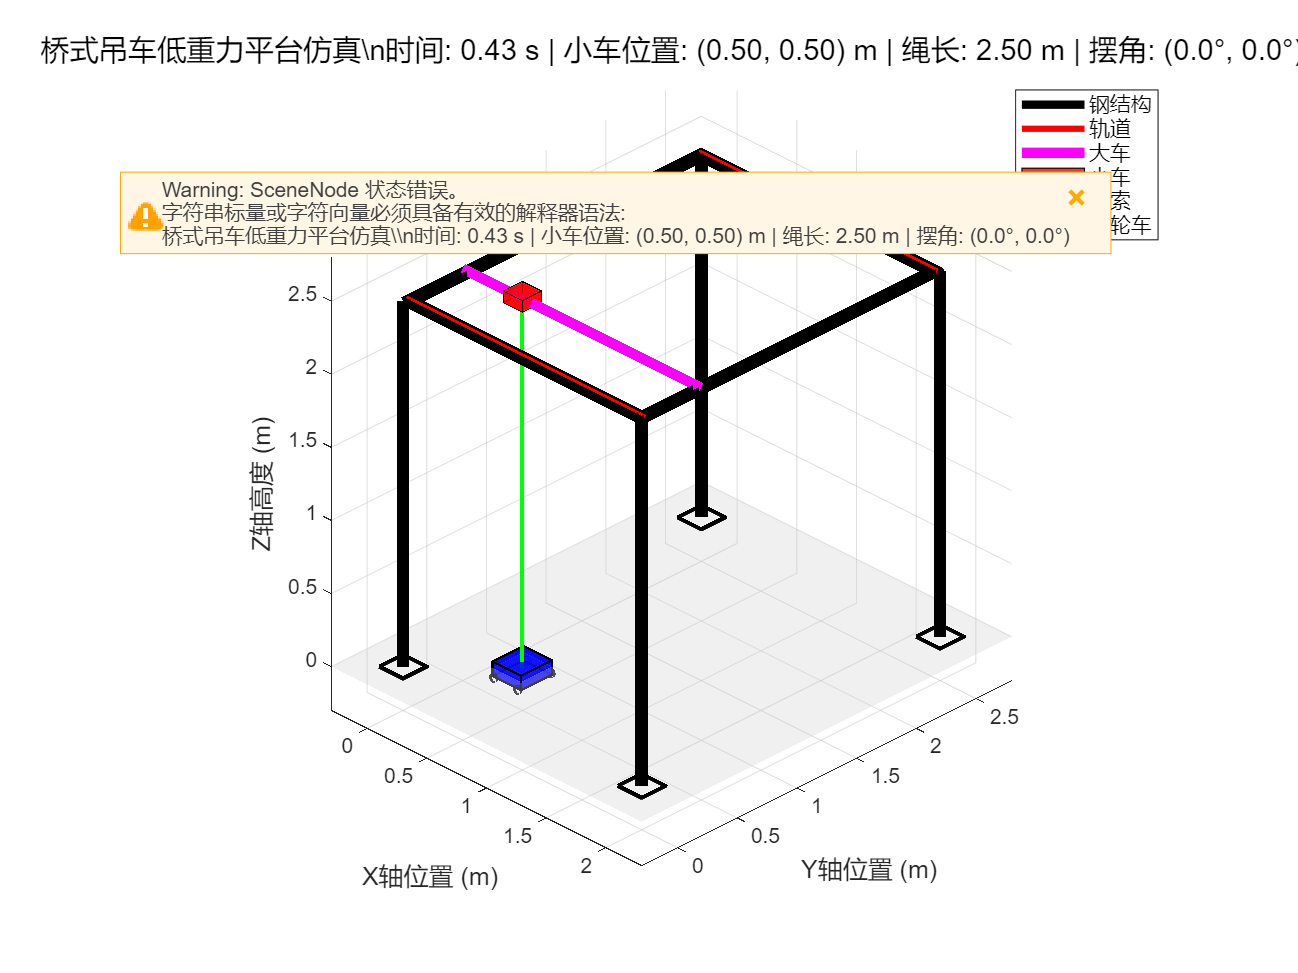


%% 三维可视化
animatecart(all_time, all_states(:,1), all_states(:,3), all_states(:,5), ...
           all_states(:,7), all_states(:,9), p);


%% 绘图
fprintf('生成结果图表...\n');

% 图1: 系统状态
figure('Name','系统动态响应','Position',[100 100 1200 800]);
subplot(2,3,1);
plot(all_time, all_states(:,1), 'b-', 'LineWidth', 1.5); hold on;%提取all_states 所有行的第一列
plot(all_time, all_states(:,3), 'r-', 'LineWidth', 1.5);%提取all_states 所有行的第三列
yline(p.x_min, 'b--', 'X_{min}'); yline(p.x_max, 'b--', 'X_{max}');%标记x轴最小限位
yline(p.y_min, 'r--', 'Y_{min}'); yline(p.y_max, 'r--', 'Y_{max}');%标记x轴最大限位
title('小车位置'); xlabel('时间 (s)'); ylabel('位置 (m)');
legend('X位置', 'Y位置', 'Location', 'best'); grid on;

subplot(2,3,2);
plot(all_time, all_states(:,2), 'b-', 'LineWidth', 1.5); hold on;%提取速度向量
plot(all_time, all_states(:,4), 'r-', 'LineWidth', 1.5);%提取y轴速度向量
title('小车速度'); xlabel('时间 (s)'); ylabel('速度 (m/s)');
legend('X速度', 'Y速度', 'Location', 'best'); grid on;

subplot(2,3,3);
plot(all_time, all_states(:,5), 'g-', 'LineWidth', 1.5);%提取绳索长度
yline(p.l_min, 'g--', 'L_{min}'); yline(p.l_max, 'g--', 'L_{max}');
title('绳长'); xlabel('时间 (s)'); ylabel('长度 (m)');
legend('绳长', 'Location', 'best'); grid on;

subplot(2,3,4);
plot(all_time, all_states(:,7)*180/pi, 'b-', 'LineWidth', 1.5); hold on;%提取x轴倾角
plot(all_time, all_states(:,9)*180/pi, 'r-', 'LineWidth', 1.5);%提取y轴倾角
title('摆动角度'); xlabel('时间 (s)'); ylabel('角度 (度)');
legend('θ_x', 'θ_y', 'Location', 'best'); grid on;

subplot(2,3,5);
plot(all_time, all_states(:,8)*180/pi, 'b-', 'LineWidth', 1.5); hold on;
plot(all_time, all_states(:,10)*180/pi, 'r-', 'LineWidth', 1.5);
title('摆动角速度'); xlabel('时间 (s)'); ylabel('角速度 (度/s)');
legend('ω_x', 'ω_y', 'Location', 'best'); grid on;

subplot(2,3,6);
plot(all_time, outputs.tension, 'k-', 'LineWidth', 1.5);
title('绳索张力'); xlabel('时间 (s)'); ylabel('张力 (N)');
grid on;

% 图2: 控制输入
figure('Name','控制输入','Position',[150 150 800 600]);
subplot(2,1,1);
plot(all_time, outputs.control_inputs(:,1), 'b-', 'LineWidth', 1.5); hold on;
plot(all_time, outputs.control_inputs(:,2), 'r-', 'LineWidth', 1.5);
plot(all_time, outputs.control_inputs(:,3), 'g-', 'LineWidth', 1.5);
title('平台加速度指令'); xlabel('时间 (s)'); ylabel('加速度 (m/s²)');
legend('ddcx', 'ddcy', 'ddcl', 'Location', 'best'); grid on;

subplot(2,1,2);
plot(all_time, outputs.control_inputs(:,4), 'b-', 'LineWidth', 1.5); hold on;
plot(all_time, outputs.control_inputs(:,5), 'r-', 'LineWidth', 1.5);
plot(all_time, outputs.control_inputs(:,6), 'g-', 'LineWidth', 1.5);
title('主动施加于负载的力'); xlabel('时间 (s)'); ylabel('力 (N)');
legend('f_{mx}', 'f_{my}', 'f_{mz}', 'Location', 'best'); grid on;

figure('Name','力和实际加速度','Position',[150 150 800 600]);
subplot(2,1,1);
plot(all_time, outputs.actual_acc(:,1), 'b-', 'LineWidth', 1.5); hold on;
plot(all_time, outputs.actual_acc(:,2), 'r-', 'LineWidth', 1.5);
plot(all_time, outputs.actual_acc(:,3), 'g-', 'LineWidth', 1.5);
title('平台实际加速度'); xlabel('时间 (s)'); ylabel('加速度 (m/s²)');
legend('ddx', 'ddy', 'lddl', 'Location', 'best'); grid on;

subplot(2,1,2);
plot(all_time, outputs.control_inputs(:,4), 'b-', 'LineWidth', 1.5); hold on;
plot(all_time, outputs.control_inputs(:,5), 'r-', 'LineWidth', 1.5);
plot(all_time, outputs.control_inputs(:,6), 'g-', 'LineWidth', 1.5);
title('主动施加于负载的力'); xlabel('时间 (s)'); ylabel('力 (N)');
legend('f_{mx}', 'f_{my}', 'f_{mz}', 'Location', 'best'); grid on;

fprintf('仿真和绘图完成！\n');
%% 小车控制输入

function u = design_velocity_profile(t)
    % 设计期望的速度轨迹 (梯形速度曲线)
    % u = [v_des_x; v_des_y; v_des_l; f_mx; f_my; f_mz]
    
    % X方向速度指令：从 t=1 到 t=5，加速到 0.2m/s
    v_des_x = trapezoidal_vel(t, 1.0, 5.0, 1.0, 0.2);
    % Y方向速度指令：从 t=2 到 t=6，加速到 0.15m/s
    v_des_y = trapezoidal_vel(t, 2.0, 6.0, 0.8, 0.15);
    % L方向速度指令：从 t=7 到 t=11，减速至 -0.1m/s（绳长缩短）
    v_des_l = trapezoidal_vel(t, 7.0, 11.0, 1.0, -0.1);

    % 施加于负载的主动力
    f_mx = 0; f_my = 0; f_mz = 0;
    if t >= 8.0 && t < 10.0
        f_mx = 5.0;%小车的x轴主动力
    end
    if t >= 11.0 && t < 12.0
        f_my = -4.0;%小车y轴主动力
    end
    
    u = [v_des_x; v_des_y; v_des_l; f_mx; f_my; f_mz];%返回完整的控制向量
end

% 生成梯形速度曲线
function v = trapezoidal_vel(t, t_start, t_end, t_accel, v_max)
    % 生成梯形速度曲线
    % 输入：时间点 t，起止时间，加速时间，最大速度
    % 输出：时间 t 时的速度值
    t_decel = t_accel;% 减速时间与加速时间相同
    if t < t_start || t > t_end
        v = 0;% 超出时间段返回0
    elseif t < (t_start + t_accel) % 加速段
        v = v_max * (t - t_start) / t_accel;% 加速段
    elseif t < (t_end - t_decel) % 匀速段
        v = v_max;% 匀速段
    else % 减速段
        v = v_max * (t_end - t) / t_decel;
    end
end

function dydt = nonlinear_dynamics_with_limits(t, y, p, control_profile)
    % 带限位检查的动力学函数
    
    % 获取期望控制输入
    control_inputs = control_profile(t);
    
    % 检查是否在边界处，如果是则修改加速度指令
     x = y(1); y_pos = y(3); l = y(5);
    
    if (x <= p.x_min && control_inputs(1) < 0) || (x >= p.x_max && control_inputs(1) > 0)
        control_inputs(1) = 0;
    end
    if (y_pos <= p.y_min && control_inputs(2) < 0) || (y_pos >= p.y_max && control_inputs(2) > 0)
        control_inputs(2) = 0;
    end
    if (l <= p.l_min && control_inputs(3) < 0) || (l >= p.l_max && control_inputs(3) > 0)
        control_inputs(3) = 0;
    end
    
    dydt = nonlinear_dynamics(t, y, p, control_inputs);
end

%%
function d_state_vec = nonlinear_dynamics(t, state, p, control_inputs)
    % 动力学核心函数：输入当前状态和控制输入，输出状态导数向量（加速度等）
    %状态变量
    x = state(1);% 小车x位置
    dx = state(2);% 小车x速度
    y = state(3);% 小车y位置
    dy = state(4);% 小车y速度
    l = state(5);% 绳长
    dl = state(6); % 绳长变化率
    th_x = state(7); % x方向摆角
    dth_x = state(8);% x方向摆角速度
    th_y = state(9);% y方向摆角
    dth_y = state(10);% y方向摆角速度
    
    v_des_x = control_inputs(1);% 期望x速度
    v_des_y = control_inputs(2); % 期望y速度
    v_des_l = control_inputs(3); % 期望绳长速度
    f_mx = control_inputs(4);% x方向扰动力
    f_my = control_inputs(5); % y方向扰动力
    f_mz = control_inputs(6); % z方向扰动力

    %由一阶惯性环节计算加速度
    ddx = (v_des_x - dx) / p.tau_x;  
    ddy = (v_des_y - dy) / p.tau_y; 
    ddl = (v_des_l - dl) / p.tau_l;  
    
    m = p.m; mx = p.m_x; my = p.m_y; g = p.g;
    Dx = p.D_x; Dy = p.D_y; Dl = p.D_l; 

    sx = sin(th_x);cx = cos(th_x);
    sy = sin(th_y);cy = cos(th_y);
    
    %惯性矩阵（M）
    M = zeros(5,5);
    M(1,1) = mx+m; M(1,3) = m*sx; M(1,4) = m*l*cx;
    M(2,2) = my+m; M(2,4) = m*l*sy*cx; M(2,5)=m*l*cy*cx;
    M(3,1) = m*sx; M(3,2) = m*sy*cx; M(3,3) = m;
    M(4,1) = m*l*cx;M(4,2) = -m*l*sx*sy;M(4,4)=m*l^2;
    M(5,2) = m*l*cy*cx;M(5,5)=m*l^2*cx^2;

    %柯氏力矩阵
    C = zeros(5,5);
    C(1,3) = 2*m*cx*dth_x; C(1,4) = 2*m*cx*dl-m*l*sx*dth_x;
    C(2,3) = 2*m*(cy*cx*dth_y-sx*sy*dth_x);
    C(2,4) = -m*(l*sy*cx*dth_x+2*l*sx*cy*dth_y+2*sy*sx*dl);
    C(2,5) = -m*(l*cx*cy*dth_y+2*l*sx*cy*dth_x-2*sy*sx*dl);
    C(3,4) = -m*l*dth_x;C(3,5) = -m*l*cx^2*dth_y;
    C(4,1) = m*dl*cx-2*m*l*sx*dth_x;
    C(4,2) = -2*m*(l*sy*cx*dth_x+l*cy*sx*dth_y+sy*sx*dl);
    C(4,3) = m*(dx*cx+2*l*dth_x-2*dy*sx*sy);
    C(4,4) = 2*m*(l*dl-l*dx*sx-l*dy*sy*cx);
    C(4,5) = m*(l^2*sx*cx*dth_y-2*l*dy*cy*sx);
    C(5,2) = 2*m*(cy*cx*dl-l*sy*cx*dth_y-l*cy*sx*dth_x);
    C(5,3) = 2*m*(dy*cx*cy+l*cx^2*dth_y);
    C(5,4) = -2*m*(l*dy*cy*sx+l^2*cx*sx*dth_y);
    C(5,5) = -2*m*(l*dy*sy*cx+l^2*cx*sx*dth_x-l*cx^2*dl);

    %G
    G = zeros(5,1);
    G(3)=-m*g*cx*cy;% 沿竖直方向
    G(4)=m*g*l*sx*cy;% θ_x 方向
    G(5)=m*g*l*cx*sy;% θ_y 方向
    
    %计算ddx与ddy
    M_ang_lhs = M(4:5, 4:5);%提取与角加速度相关的惯性项，2*2的子矩阵
    M_ang_rhs_terms_coeff = M(4:5, 1:3);%角运动方程中的线性加速度耦合项。

    Q_theta_x_payload = l*(f_mx*cx - f_my*sy*sx + f_mz*sx*cy);%小车对相对于x小车的主动力矩
    Q_theta_y_payload = l*cx*(f_my*cy + f_mz*sy);%小车相对于y小车的主动力矩
    Q_payload = [Q_theta_x_payload; Q_theta_y_payload];
    q_dot = [dx; dy; dl; dth_x; dth_y];
    C_term_ang = C(4:5, :) * q_dot; % 提取角方向柯氏力影响项
    %由一阶惯性环节输出的加速度
     known_platform_accelerations = [ddx; ddy; ddl];

     b_vector_ang = Q_payload - (C_term_ang + G(4:5) + ...
                   M_ang_rhs_terms_coeff * known_platform_accelerations);%角运动的总等效力矩
   angular_accelerations = M_ang_lhs \ b_vector_ang;%求解等效角加速度
    ddth_x = angular_accelerations(1);
    ddth_y = angular_accelerations(2);
    
    %ddX
    d_state_vec = zeros(10,1);
    d_state_vec(1) = dx;
    d_state_vec(2) = ddx; % Commanded
    d_state_vec(3) = dy;
    d_state_vec(4) = ddy; % Commanded
    d_state_vec(5) = dl;
    d_state_vec(6) = ddl; % Commanded
    d_state_vec(7) = dth_x;
    d_state_vec(8) = ddth_x;      % Calculated
    d_state_vec(9) = dth_y;
    d_state_vec(10) = ddth_y;     % Calculated
end

function T_rope = tension(current_t, current_state_vec, p, actual_ddx, actual_ddy, actual_ddl, f_mx, f_my, f_mz)

% 计算当前时刻绳索张力的函数
    % 输入：当前时间、状态向量、参数结构体、实际加速度、外部扰动力
    % 输出：绳索张力 T_rope

    % 提取当前状态变量
    l_i = current_state_vec(5);       % 当前绳长
    dl_i = current_state_vec(6);      % 当前绳长变化率
    th_x_i = current_state_vec(7);    % 当前θ_x
    dth_x_i = current_state_vec(8);   % 当前θ_x导数
    th_y_i = current_state_vec(9);    % 当前θ_y
    dth_y_i = current_state_vec(10);  % 当前θ_y导数

    sx_i = sin(th_x_i); cx_i = cos(th_x_i);
    sy_i = sin(th_y_i); cy_i = cos(th_y_i);
    % 负载主动力在绳索方向上的合力分量（抵消张力的力）
    payload_force_on_tension = f_mx * sx_i + f_my * sy_i * cx_i - f_mz * cx_i * cy_i;

    % 张力计算（基于牛顿第二定律在绳方向上的投影）
    T_rope = p.m * actual_ddl ...                       % 质量×绳长加速度分量
           + p.m * actual_ddx * sx_i ...               % X方向加速度分量投影
           + p.m * actual_ddy * sy_i * cx_i ...        % Y方向加速度分量投影
           - p.m * l_i * dth_x_i^2 ...                 % θ_x 产生的向心力分量
           - p.m * l_i * dth_y_i^2 * cx_i^2 ...        % θ_y 的向心力在绳方向分量
           - p.m * p.g * cx_i * cy_i ...               % 重力在绳方向分量
           + p.D_l * dl_i ...                          % 绳长阻尼力
           - payload_force_on_tension;                 % 外部扰动力沿绳方向的抵消项
end